Running k-Wave simulation...
  start time: 09-Mar-2023 21:47:14
  reference sound speed: 5100m/s
  dt: 22.9779ns, t_end: 47.1278us, time steps: 2052
  input grid size: 128 by 128 grid points (50 by 50mm)
  maximum supported frequency: 1.92MHz
  expanding computational grid...
  computational grid size: 168 by 168 grid points
  precomputation completed in 0.49463s
  starting time loop...
  estimated simulation time 22.2316s...


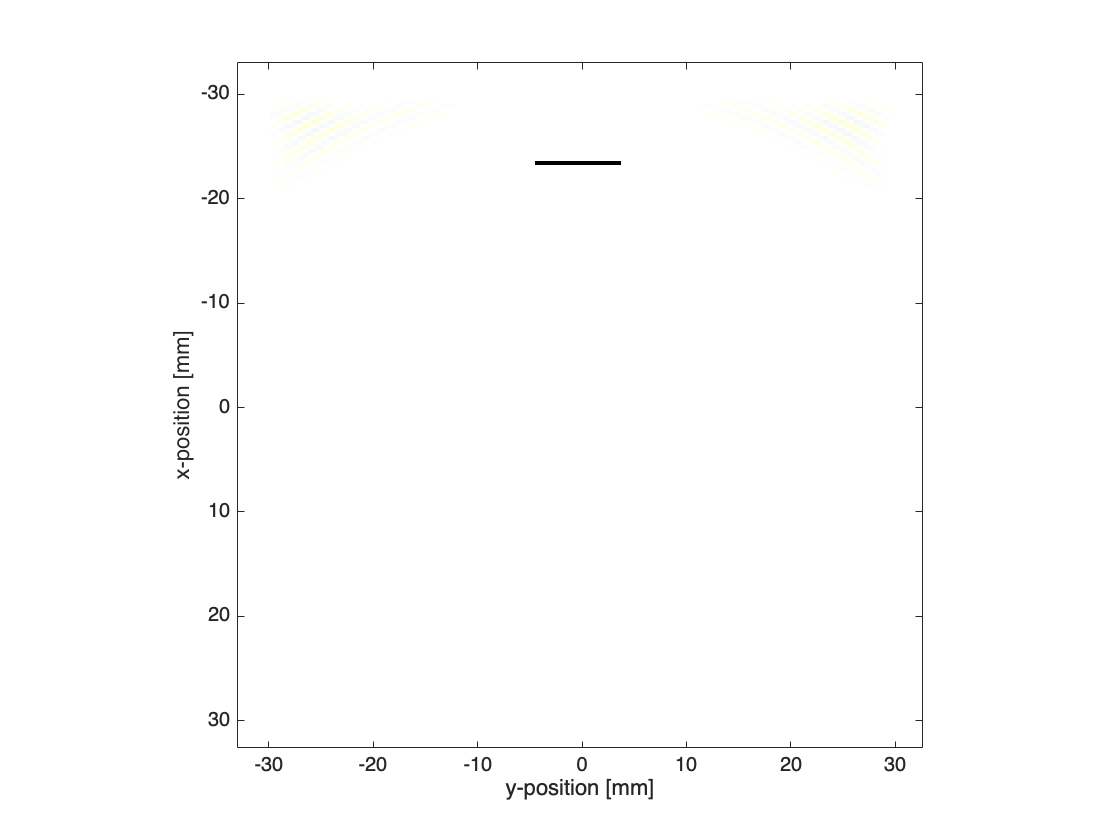

  simulation completed in 21.9091s
  total computation time 22.7063s


clearvars;
% create the computational grid
Nx = 128;           % number of grid points in the x (row) direction
Ny = Nx;            % number of grid points in the y (column) direction
dx = 50e-3/Nx;    	% grid point spacing in the x direction [m]
dy = dx;            % grid point spacing in the y direction [m]
kgrid = kWaveGrid(Nx, dx, Ny, dy);

% define sound speed in the two layers
c1 = 1500;          % [m/s]
%c2 = 1600;         % sediment
c2 = 5100;          % aluminium
% define the properties of the propagation medium
medium.sound_speed = c1 * ones(Nx, Ny);     % [m/s]
medium.sound_speed(Nx/2:end, :) = c2;       % [m/s]
medium.density = 1000 * ones(Nx, Ny);       % [kg/m^3]
medium.density(Nx/2:end, :) = 2700;         % aluminium
%medium.density(Nx/2:end, :) = 1500;        % sediment
medium.alpha_coeff = 0.75;                  % [dB/(MHz^y cm)]
medium.alpha_power = 1.5;

% create the time array
kgrid.makeTime(medium.sound_speed);
% I had to increase the number of time steps Nt because the simulation was
% ending too early to view the whole backscatter plot. I used the
% kgrid.makeTime() method to see what the algorithm had used, then manually
% set kgrid.dt to be the same and kgrid.Nt to be slightly larger until the
% simulation ran for an appropriate amount of time - for sediment, not Al
%kgrid.Nt = 740;
%kgrid.dt = 7.3242e-8;
% define a source mask for a linear element transducer with an odd number
% of elements

num_elements = 21;
source.p_mask = zeros(Nx, Ny);
x_offset = 5;
y_offset = 20;
start_index = Ny/2 - round(num_elements/2) + 1;
source.p_mask(x_offset, start_index:start_index + num_elements - 1) = 1;

% define the properties of the tone burst
sampling_freq = 1/kgrid.dt;     % [Hz]
steering_angle = 0;            % [deg]
element_spacing = dx;           % [m]
tone_burst_freq = 1e6;          % [Hz]
tone_burst_cycles = 8;

% create an element index relative to the centre element of the transducer
element_index = -(num_elements - 1)/2:(num_elements - 1)/2;

% use geometric beam forming to calculate the tone burst offsets for each
% transducer element based on the element index
tone_burst_offset = 200 + element_spacing * element_index * ...
    sin(steering_angle * pi/180) / (c1 * kgrid.dt);

% create the tone burst signals
source.p = toneBurst(sampling_freq, tone_burst_freq, tone_burst_cycles, ...
    'SignalOffset', tone_burst_offset);

% assign the input options
input_args = {'DisplayMask', source.p_mask, 'PMLInside', false};

%define sensor mask
sensor.mask = zeros(Nx, Ny);
sensor.mask(x_offset, start_index:start_index + num_elements - 1) = 1;

% run the simulation
sensor_data = kspaceFirstOrder2D(kgrid, medium, source, sensor, input_args{:});

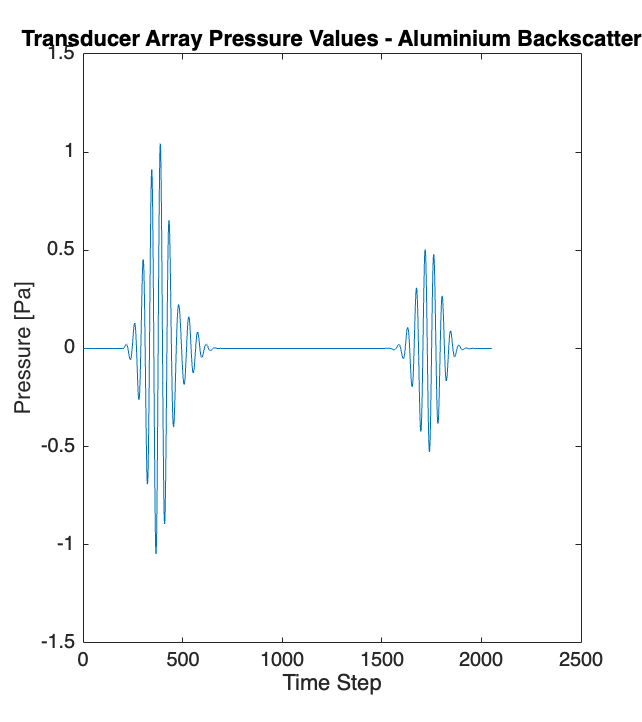


%plot pressure data at middle element
mid_element = round(num_elements/2);
figure;
plot(sensor_data(mid_element, :));
xlabel('Time Step');
ylabel('Pressure [Pa]');
title("Transducer Array Pressure Values - Aluminium Backscatter")
scaleFig(1, 1.5);